# **TRATAMIENTO DIGITAL DE IMAGENES**

#### **Máster Universitario en Visión Artificial (URJC). **

## **Autor: Vicente Gilabert Mañó**

**Práctica 2: Segmentación basada en regiones y morfología matemática****.**

**2.B.- Desarrollar un programa que utilice la combinación de operaciones de morfología matemática vistas en clase o cualquier otra combinación que estime conveniente para la detección de esquinas en imágenes en escala de grises. Puede utilizar todas las operaciones previas que estime convenientes. Comente los resultados obtenidos.**

Para la realización de la práctica, se ha desarrollado la siguiente función:

**[result,corners] = morphCornerDetector(img,num_op,debugMode,showResult): **Esta función realiza la deteción de bordes mediante operaciones morfológicas.

- Con *num_op *se puede configurar el numero de iteraciones para cada operacion dilate y erode.

- Con *debugMode*=1 se pueden ver los pasos que realiza el algoritmo *(Close1 y Close2)*.

- Con *showResults*=1 se muestra el resultado de la fusion entre la imagen original y la deteccion de bordes. 

- La salida de la funcion es la imagen fusionada *result* (imagen con la deteccion de bordes) y la imagen binaria de la deteccion de bordes (*corners*).

La práctica se divide en tres secciones diferentes:

- (1) Detección de bordes en tres imágenes diferentes.

- (2) Modificación del algoritmo para obtener un resultado diferente en la detección de bordes.

- (3) Conclusiones de la práctica.

## (1) Deteccion de bordes en tres imagenes diferentes.

clear all;

img1 = imread("images/edificio1.jpg");
img2 = imread("images/edificio2.png");
img3 = imread("images/barco.jpg");
debugMode=1;
showResults=1;

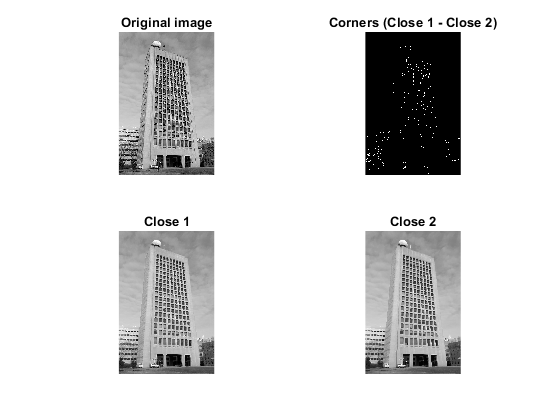

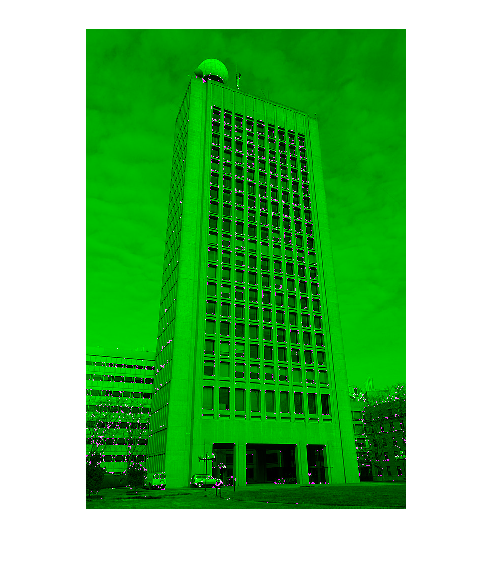

[result1,corners1] = morphCornerDetector(img1, [1 1 1 1], debugMode, showResults);

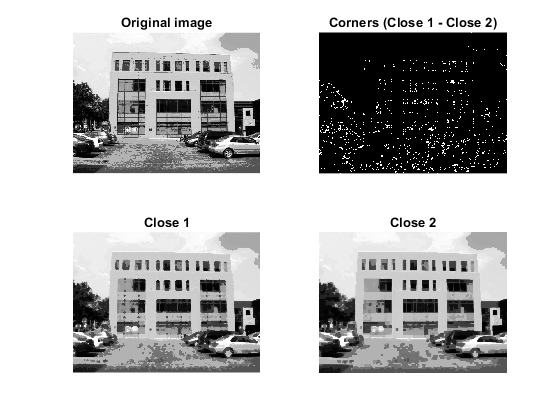

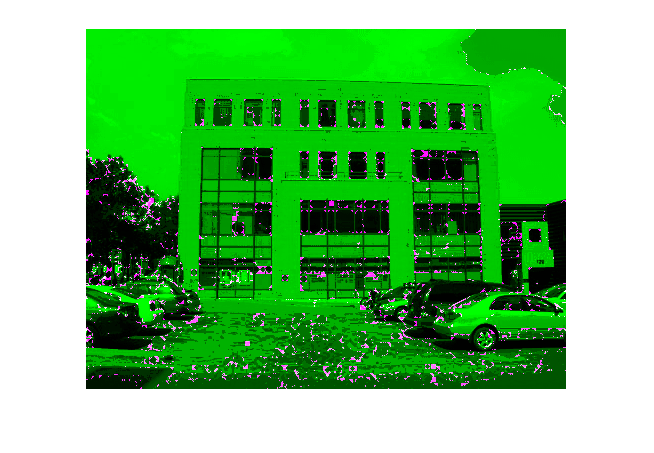

[result2,corners2] = morphCornerDetector(img2, [1 1 1 1], debugMode, showResults);

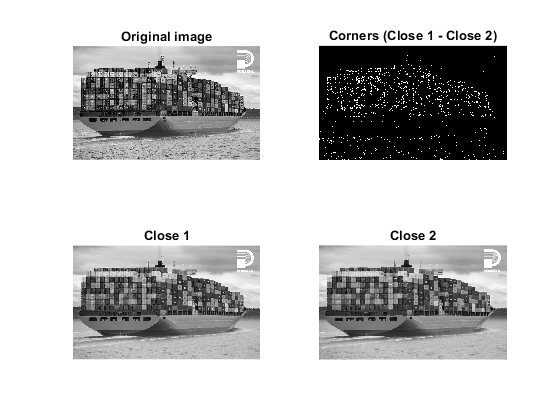

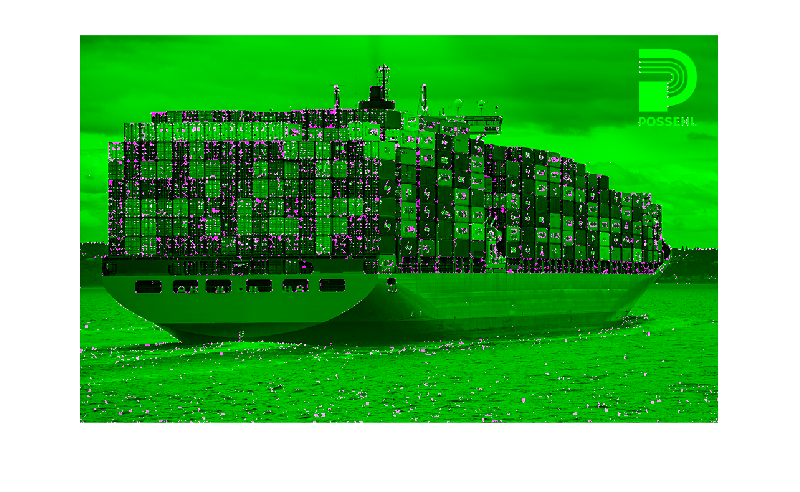


[result3,corners3] = morphCornerDetector(img3, [1 1 1 1], debugMode, showResults);

## (2) Pequeña modificación del algoritmo.

Se han realizado algunas pruebas para conseguir una mejor deteccion de bordes. 

Se ha añadido una iteracion más en el erode del *close2*. Con esto se consigue hacer una máscara más pequeña, por lo que los bordes son más definidos.

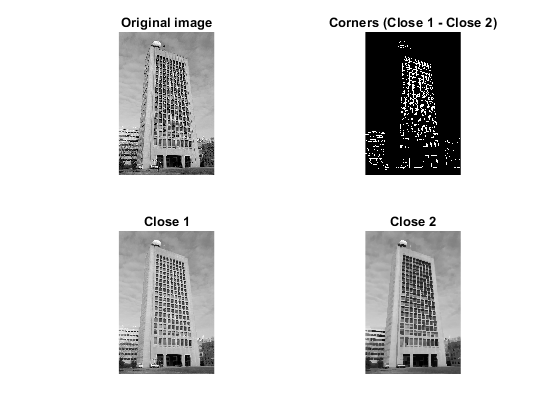

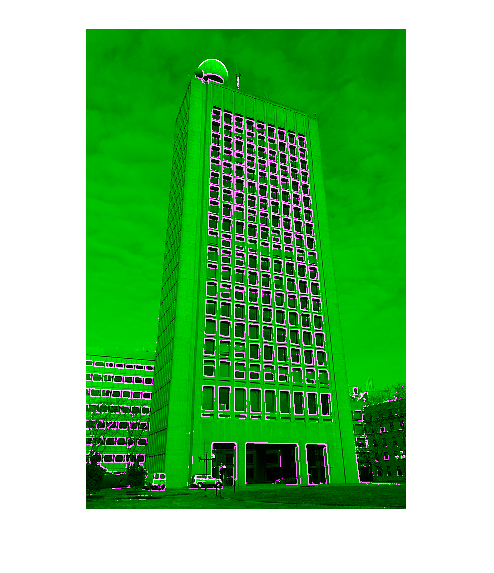

[result1,corners1] = morphCornerDetector(img1, [1 1 1 2], debugMode, showResults);

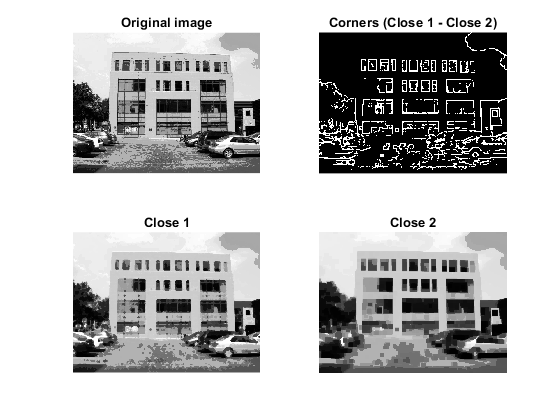

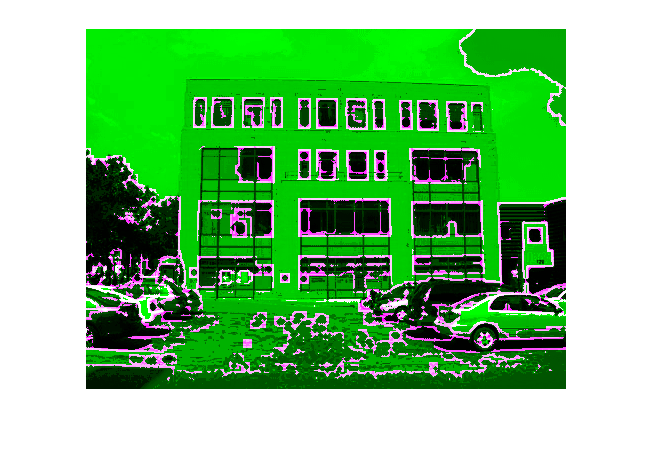

[result2,corners2] = morphCornerDetector(img2, [1 1 1 2], debugMode, showResults);

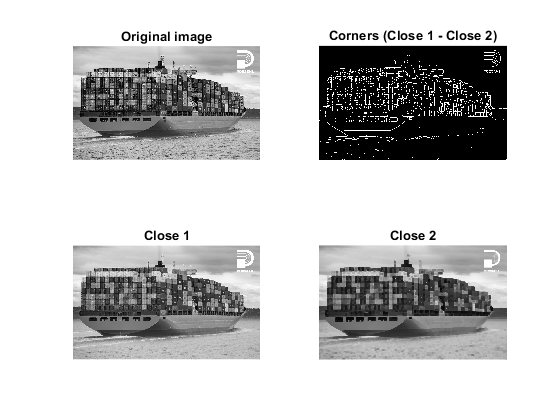

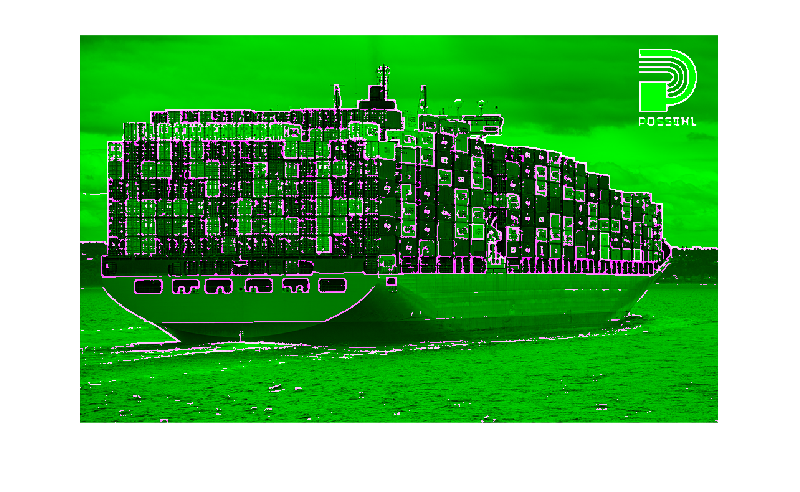

[result3,corners3] = morphCornerDetector(img3, [1 1 1 2], debugMode, showResults);

## **(3) CONCLUSIONES**

- Se ha desarrollado la función para la detección de bordes mediante operaciones morfológicas.

- La función es parametrizable para poder elegir el número de iteraciones en cada operación morfológica. 

- Se han realizado diferentes pruebas para obtener un resultado donde los bordes estan más definidos.